**Planta com disturbio e sem controlador geral**

% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Identificacao\Dados disturbio sem controlador\sem-controle-19ms-11.97V-ajs-acc-susp-06-02-2024 17-08.csv");
% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\10V-dados-cotrolador-on-e-off-susp-08-02-2024 16-34.csv");

% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\9V-dados-controlador-H2-on-e-off-susp-09-02-2024 14-25.csv");
% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\10V-dados-controlador-H2-on-e-off-susp-09-02-2024 14-05.csv");
% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-dados-controlador-H2-on-e-off-susp-09-02-2024 14-15.csv");
% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\9V-mola-media-susp-09-02-2024 16-13.csv");
% plantaGeralNoU = readtable("C:\Users\luiza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\10V-mola-media-susp-09-02-2024 16-56.csv");
% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-mola-media-susp-09-02-2024 16-41.csv");
% plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-mola-media-H2-ontem-susp-09-02-2024 16-45.csv");
plantaGeralNoU = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-crtl-final-susp-16-02-2024 13-09.csv");

flagNoU = plantaGeralNoU.CONTROLLER_FLAG == 0;

aceleracaoPlantaGeralNoU = plantaGeralNoU.Sprung_acceleration_x(flagNoU, :);
aceleracaoPlantaGeralNoU = aceleracaoPlantaGeralNoU(200:end, :);

Ts = 19e-3;
[N, ~] = size(aceleracaoPlantaGeralNoU);
tNoU = linspace(0, N, N)';

% Potencia do sinal
WNoU = 1/N * aceleracaoPlantaGeralNoU'*aceleracaoPlantaGeralNoU

WNoU =           7.72926130017452


% Valor RMS da aceleração vertical
rmsNoU = rms(aceleracaoPlantaGeralNoU)

rmsNoU =           2.78015490578754


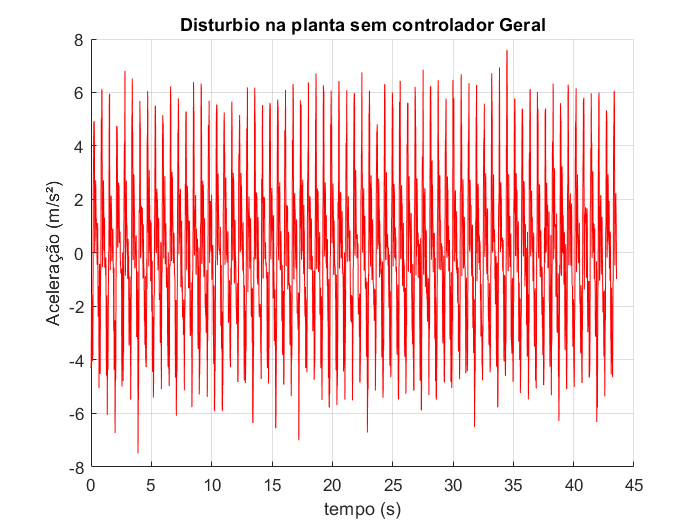

figure
hold on
grid

xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tNoU*Ts, aceleracaoPlantaGeralNoU,'r-');
title("Disturbio na planta sem controlador Geral");
% axis([10 12 -15 15])
% legend("Disturbio senoidal 11.97V");

hold off

**Disturbio do motor em vazio**

wMotor = readtable("\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Identificacao\motor-free-low-pass-6-susp-06-02-2024 11-09.csv");

setPointVazio = wMotor.U;
posicaoVazio = wMotor.SL_position;
aceleracaoVazio = wMotor.Sprung_acceleration_x;

Ts = 19e-3;
[NVazio, ~] = size(setPointVazio);
tVazio = linspace(0, NVazio, NVazio)';

% Potencia do sinal
WVazio = 1/N * aceleracaoVazio'*aceleracaoVazio

WVazio =          0.877918979057592


% Valor RMS da aceleração vertical
rmsVazio = rms(aceleracaoVazio)

rmsVazio =           1.11038720392801


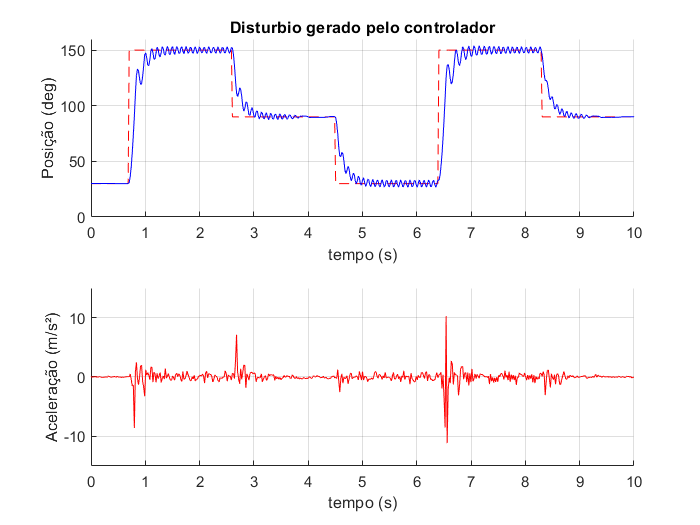


figure
subplot(211);
title("Disturbio gerado pelo controlador");
hold on
grid

xlabel("tempo (s)")
ylabel("Posição (deg)");
plot(tVazio*Ts, setPointVazio,'r--');
plot(tVazio*Ts, posicaoVazio,'b-');
axis([0 10 0 160])

hold off

subplot(212);
hold on
grid

xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(tVazio*Ts, aceleracaoVazio,'r-');
axis([0 10 -15 15])

hold off

**Planta com controlador geral**

% plantaGeralControlada = readtable("\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Identificacao\2controlador-susp-06-02-2024 13-59.csv");
% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\10V-dados-cotrolador-on-e-off-susp-08-02-2024 16-34.csv");

% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\9V-dados-controlador-H2-on-e-off-susp-09-02-2024 14-25");
% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\10V-dados-controlador-H2-on-e-off-susp-09-02-2024 14-05.csv");
% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-dados-controlador-H2-on-e-off-susp-09-02-2024 14-15");
% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\9V-mola-media-susp-09-02-2024 16-13.csv");
% plantaGeralControlada = readtable("C:\Users\luiza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\10V-mola-media-susp-09-02-2024 16-56.csv");
% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-mola-media-susp-09-02-2024 16-41.csv");
% plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-mola-media-H2-ontem-susp-09-02-2024 16-45.csv");
plantaGeralControlada = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\12V-crtl-final-susp-16-02-2024 13-09.csv");

flag = plantaGeralControlada.CONTROLLER_FLAG > 0;
setPoint = plantaGeralControlada.U(flag, :);
posicao = plantaGeralControlada.SL_position(flag, :);
aceleracao = plantaGeralControlada.Sprung_acceleration_x(flag, :);

setPoint = setPoint(200:end, :);
posicao = posicao(200:end, :);
aceleracao = aceleracao(200:end, :);

Ts = 19e-3;
[N, ~] = size(setPoint);
t = linspace(0, N, N)';

% Potencia do sinal
WU = 1/N * aceleracao'*aceleracao

WU =           6.11101202478175


% Valor RMS da aceleração vertical
rmsU = rms(aceleracao)

rmsU =           2.47204612108709


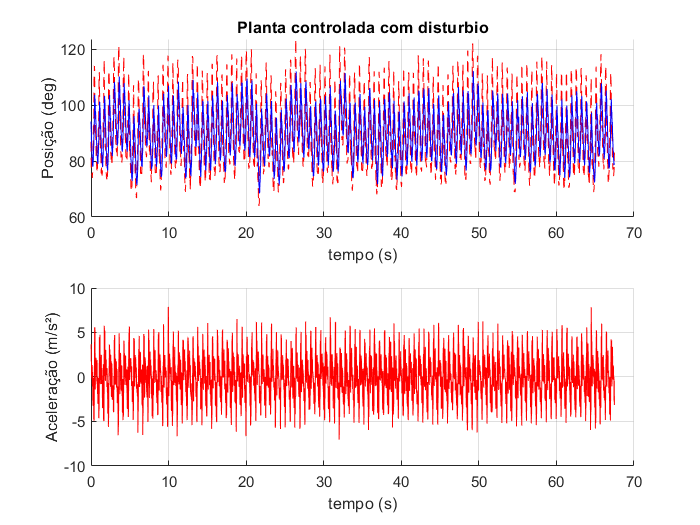


figure
subplot(211);
title("Planta controlada com disturbio");
hold on
grid

xlabel("tempo (s)")
ylabel("Posição (deg)");
plot(t*Ts, setPoint,'r--');
plot(t*Ts, posicao,'b-');
% axis([10 12 0 160])

hold off

subplot(212);
hold on
grid

xlabel("tempo (s)")
ylabel("Aceleração (m/s²)");
plot(t*Ts, aceleracao,'r-');
% axis([10 12 -15 15])

hold off

disp("Potencia sem U | Potencia com U | Variação(%)")

Potencia sem U | Potencia com U | Variação(%)


disp(WNoU + " | " + WU + " | " + (WU - WNoU)/WNoU * 100)

7.7293 | 6.111 | -20.9367


disp("Aceleração RMS sem U | Aceleração RMS com U | Variação(%)")

Aceleração RMS sem U | Aceleração RMS com U | Variação(%)


disp(rmsNoU + " | " + rmsU + " | " + (rmsU - rmsNoU)/rmsNoU * 100)

2.7802 | 2.472 | -11.0824


dinamicaServo = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\cov-sin-1e-5-1e-1-susp-09-02-2024 15-48.csv");
% dinamicaServoCov = readtable("C:\Users\Luiz Souza\OneDrive\Aulas Faculdade\TCC\Repos\Projeto controlador\Controlador geral\cov-sin-1e-5-1e-6-susp-09-02-2024 15-50.csv");

dinamicaServoSetPoint = dinamicaServo.U;
dinamicaServoPosition = dinamicaServo.SL_position;

% dinamicaServoSetPointCov = dinamicaServoCov.U;  
% dinamicaServoPositionCov = dinamicaServoCov.SL_position;

dinamicaServoTs = 1e-3;
[dinamicaServoN, ~] = size(dinamicaServoSetPoint);
dinamicaServoT = linspace(0, dinamicaServoN, dinamicaServoN)';

[dinamicaServoNcov, ~] = size(dinamicaServoSetPointCov);

Unrecognized function or variable 'dinamicaServoSetPointCov'.

dinamicaServoTcov = linspace(0, dinamicaServoNcov, dinamicaServoNcov)';

figure
title("PRBS no Servo");
hold on
grid

xlabel("tempo (s)")
ylabel("Posição (deg)");
plot(dinamicaServoT*dinamicaServoTs, dinamicaServoSetPoint,'r--');
plot(dinamicaServoT*dinamicaServoTs, dinamicaServoPosition,'b-');
% plot(dinamicaServoTcov*dinamicaServoTs, dinamicaServoSetPointCov,'g--');
% plot(dinamicaServoTcov*dinamicaServoTs, dinamicaServoPositionCov,'g-');
% axis([10 12 0 160])

hold off
